Looks at how well we can fit instantaneous polymerase loading

Generates data

time_res = 20;
elong_time = 160;
points_per_trace = 100;
num_traces = 100;
num_states = 3;
fluo_per_rna = 350;
noise = 0;
rna_per_sec = [.000001, .2, .4];
rise_time = 40;
init_dist = [1 0 0];
trans_mat = [-0.0115,  0.0095,  0.0000; ...
         0.0115, -0.0180,  0.0440; ...
         0.0000,  0.0085, -0.0440];
elong_func = {'Gaussian', elong_time, 3};
[traces, arrival_traces] = gen_data_var_len(elong_func, time_res, points_per_trace, ...
    num_traces, num_states, trans_mat, rna_per_sec, ...
    fluo_per_rna, rise_time, init_dist, noise);

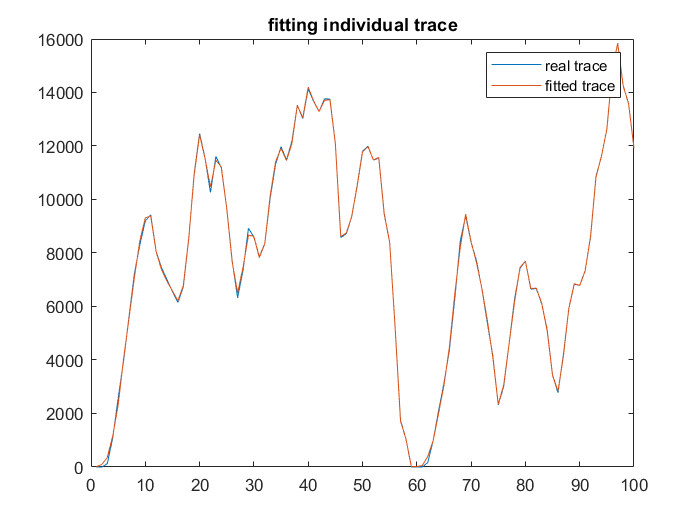

i = 18;
trace = traces{i};
arrival_trace = arrival_traces{i};
elong_time = 8; %number of time points before fall off
rise_time = 2;
num_points = length(trace);
A = zeros(num_points,num_points);
for i = 1:(num_points)
    for j = 1:elong_time
        if i + j - 1 > num_points
            break
        end
        if j <= rise_time
            A(i + j - 1, i) = j /( 2 * rise_time);
        else
            A(i + j - 1, i) = 1;
        end
    end
end
x = lsqnonneg(A, trace');   
nonzero_idxes = find(x > 0);
fitted_trace  = A * x;
figure();
plot(trace);
hold on
plot(fitted_trace);
title('fitting individual trace')
legend('real trace', 'fitted trace');

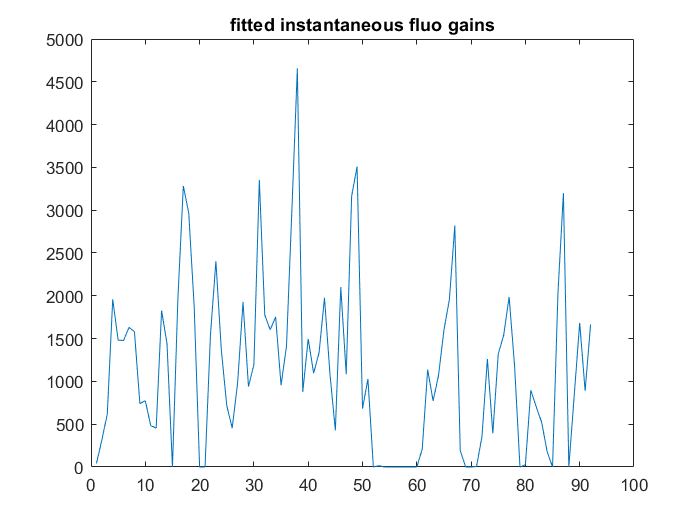


% calculates real instantaneous additions
real_instants = zeros(1, length(trace));
for i = 1:length(real_instants)
    t_start = (i - 1) * time_res;
    t_end = i * time_res;
   
    idxes = find(arrival_trace > t_start & arrival_trace < t_end);
    real_instants(i) = length(idxes) * fluo_per_rna;
    
end

figure();
plot(x(1:end-elong_time));
title('fitted instantaneous fluo gains');

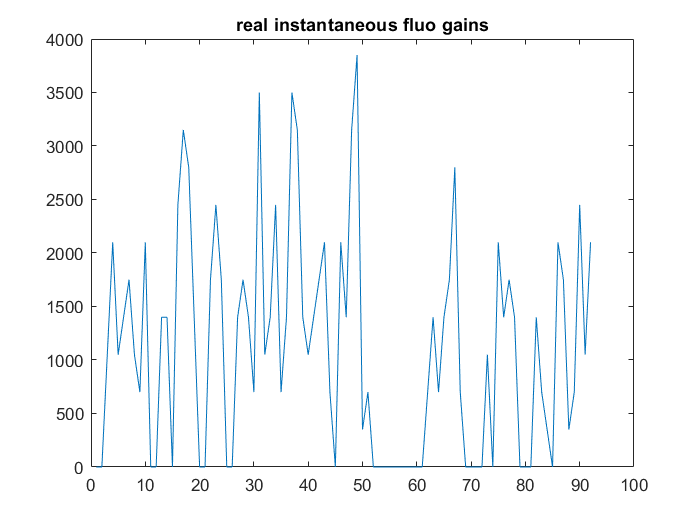


figure();
plot(real_instants(1:end-elong_time));
title('real instantaneous fluo gains');

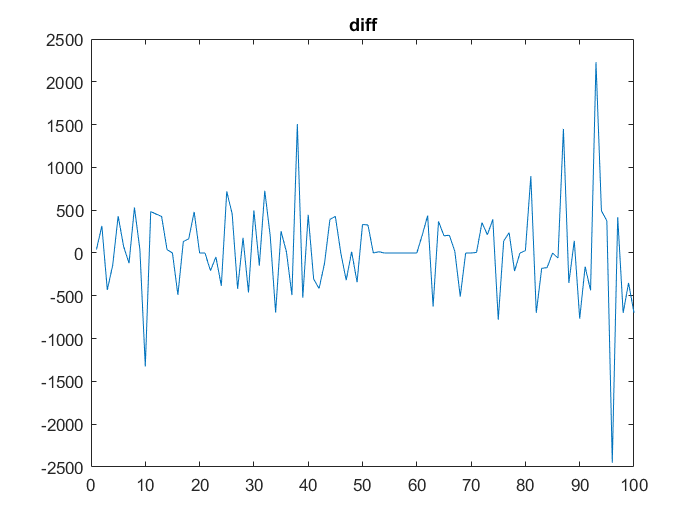


figure();
plot(x - real_instants');
title('diff');